clc;

% FIRST PART: CALCULATE INITIAL CF (for grid connection loss = 0)
T_PV= readtable("hourlyproductionPV_raw.csv")

T_PV = 8760×3 table
          time             local_time       electricity
    ________________    ________________    ___________

    2019-01-01 00:00    2019-01-01 05:45           0   
    2019-01-01 01:00    2019-01-01 06:45      84.247   
    2019-01-01 02:00    2019-01-01 07:45      406.78   
    2019-01-01 03:00    2019-01-01 08:45       630.3   
    2019-01-01 04:00    2019-01-01 09:45      762.68   
    2019-01-01 05:00    2019-01-01 10:45      832.63   
    2019-01-01 06:00    2019-01-01 11:45       846.1   
    2019-01-01 07:00    2019-01-01 12:45      805.65   
    2019-01-01 08:00    2019-01-01 13:45      707.18   
    2019-01-01 09:00    2019-01-01 14:45      546.47   
    2019-01-01 10:00    2019-01-01 15:45      300.67   
    2019-01-01 11:00    2019-01-01 16:45      17.581   
    2019-01-01 12:00    2019-01-01 17:45           0   
    2019-01-01 13:00    2019-01-01 18

T_wind= readtable("hourlyproductionWind_raw.csv")

T_wind = 8760×3 table
          time             local_time       electricity
    ________________    ________________    ___________

    2019-01-01 00:00    2019-01-01 05:45       0.483   
    2019-01-01 01:00    2019-01-01 06:45       0.349   
    2019-01-01 02:00    2019-01-01 07:45       0.153   
    2019-01-01 03:00    2019-01-01 08:45       0.037   
    2019-01-01 04:00    2019-01-01 09:45       0.009   
    2019-01-01 05:00    2019-01-01 10:45           0   
    2019-01-01 06:00    2019-01-01 11:45           0   
    2019-01-01 07:00    2019-01-01 12:45           0   
    2019-01-01 08:00    2019-01-01 13:45           0   
    2019-01-01 09:00    2019-01-01 14:45           0   
    2019-01-01 10:00    2019-01-01 15:45       0.771   
    2019-01-01 11:00    2019-01-01 16:45       0.066   
    2019-01-01 12:00    2019-01-01 17:45           0   
    2019-01-01 13:00    2019-01-01 

length_PV=height(T_PV)

length_PV = 8760

length_wind=height(T_wind)

length_wind = 8760


T_PV(:,1)=[] %eliminate first column (not local time)

T_PV = 8760×2 table
       local_time       electricity
    ________________    ___________

    2019-01-01 05:45           0   
    2019-01-01 06:45      84.247   
    2019-01-01 07:45      406.78   
    2019-01-01 08:45       630.3   
    2019-01-01 09:45      762.68   
    2019-01-01 10:45      832.63   
    2019-01-01 11:45       846.1   
    2019-01-01 12:45      805.65   
    2019-01-01 13:45      707.18   
    2019-01-01 14:45      546.47   
    2019-01-01 15:45      300.67   
    2019-01-01 16:45      17.581   
    2019-01-01 17:45           0   
    2019-01-01 18:45           0   
    2019-01-01 19:45           0   
    2019-01-01 20:45           0   


T_wind(:,1)=[]

T_wind = 8760×2 table
       local_time       electricity
    ________________    ___________

    2019-01-01 05:45       0.483   
    2019-01-01 06:45       0.349   
    2019-01-01 07:45       0.153   
    2019-01-01 08:45       0.037   
    2019-01-01 09:45       0.009   
    2019-01-01 10:45           0   
    2019-01-01 11:45           0   
    2019-01-01 12:45           0   
    2019-01-01 13:45           0   
    2019-01-01 14:45           0   
    2019-01-01 15:45       0.771   
    2019-01-01 16:45       0.066   
    2019-01-01 17:45           0   
    2019-01-01 18:45       0.399   
    2019-01-01 19:45       0.676   
    2019-01-01 20:45       0.278   


    X_localtime_PV=T_PV(:,1);
    Y_electricity_PV=T_PV(:,2);
    
    X_localtime_wind=T_wind(:,1);
    Y_electricity_wind=T_wind(:,2)

Y_electricity_wind = 8760×1 table
    electricity
    ___________

       0.483   
       0.349   
       0.153   
       0.037   
       0.009   
           0   
           0   
           0   
           0   
           0   
       0.771   
       0.066   
           0   
       0.399   
       0.676   
       0.278   



    X_PV=table2array(X_localtime_PV); %vector that contains local time data
    Y_PV=table2array(Y_electricity_PV); %vector that contains electricity data

    X_wind=table2array(X_localtime_wind); %vector that contains local time data
    Y_wind=table2array(Y_electricity_wind);

hourlyproduction_PV=plot(X_PV,Y_PV)

hourlyproduction_PV =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2019-01-01 05:45    2019-01-01 06:45    2019-01-01 07:45    2019-01-01 08:45    2019-01-01 09:45    2019-01-01 10:45    2019-01-01 11:45    2019-01-01 12:45    2019-01-01 13:45    2019-01-01 14:45    2019-01-01 15:45    …    ]
              YData: [0 84.2470 406.7790 630.2970 762.6810 832.6260 846.1030 805.6550 707.1800 546.4710 300.6660 17.5810 0 0 0 0 0 0 0 0 0 0 0 0 0 73.0700 384.1610 597.5750 730.2080 777.3880 677.7690 423.0500 358.2610 353.8730 213.8700 13.0840 0 0 0 … ]
              ZData: [1×0 double]

  Show 

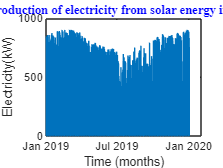

title("Hourly production of electricity from solar energy in Nepal (2019)","Color","blue","FontName","times")
xlabel("Time (months)")
ylabel("Electricity(kW)")


hourlyproduction_wind=plot(X_wind,Y_wind)

hourlyproduction_wind =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2019-01-01 05:45    2019-01-01 06:45    2019-01-01 07:45    2019-01-01 08:45    2019-01-01 09:45    2019-01-01 10:45    2019-01-01 11:45    2019-01-01 12:45    2019-01-01 13:45    2019-01-01 14:45    2019-01-01 15:45    …    ]
              YData: [0.4830 0.3490 0.1530 0.0370 0.0090 0 0 0 0 0 0.7710 0.0660 0 0.3990 0.6760 0.2780 0.1100 0.0630 0.0610 0.0590 0.0830 0.0950 0.0630 0.0130 0.0060 0.0170 0.0120 0 0 0 0 0 0 1.0000e-03 0.0090 0.0020 0 0.2120 1.4590 1.6320 1.1440 … ]
              ZData: [1×0 double]

  Show 

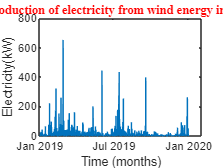

title("Hourly production of electricity from wind energy in Nepal (2019)","Color","red","FontName","times")
xlabel("Time (months)")
ylabel("Electricity(kW)")


annualprodkW_PV=sum(Y_PV);
annualprodMW_PV=annualprodkW_PV/1000;

annualprodkW_wind=sum(Y_wind);
annualprodMW_wind=annualprodkW_wind/1000;
fprintf('Annual production of electricity from wind energy (in MW) is: %s\n', annualprodMW_wind)

Annual production of electricity from wind energy (in MW) is: 7.501881e+01



CF_PV=annualprodMW_PV/(365*24*1)

CF_PV = 0.2107

CF_PV=mean(Y_PV)/1000;
CF_wind=annualprodMW_wind/(365*24)

CF_wind = 0.0086



% SECOND PART: VARIATION OF PRODUCED ENERGY BC OF GRID CONNECTION ENERGY LOSS

%data
Ct_PV=380000;
Ct_wind=1040000;
r=0.07;

n_PV=40;
n_wind=30;

OMvariable_PV = 0;
OMfixed_PV = 7250;

OMvariable_wind =1.35;
OMfixed_wind =12600;

CRF_PV = (r*(1+r)^n_PV)/((1+r)^(n_PV)-1);
CRF_wind=(r*(1+r)^n_wind)/((1+r)^(n_wind)-1);

%gc=grid connection
gc=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9];

sLCOE_PV=zeros(1,10);
sLCOE_wind=zeros(1,10);

newCF_PV=zeros(1,10);
newCF_wind=zeros(1,10);

installedcapacity=1;
newcapacity=zeros(1,10);

lost_energy_PV=zeros(1,10);
lost_energy_wind=zeros(1,10);

usable_energy_PV=zeros(1,10);
usable_energy_wind=zeros(1,10);

lost_cost_PV=zeros(1,10);
lost_cost_wind=zeros(1,10);

M_PV=zeros(10,7);
M_wind=zeros(10,7);



for i = 1:10
%column1
    gridconnection=gc(i);

%column 2
    newcapacity(i)=1-gc(i);

%column3    
    newCF_PV(i)  = (CF_PV/(1-gc(i)));
    newCF_wind(i) = (CF_wind/(1-gc(i)));

%column4    MAX USABle is the peak capacity for each gc?
    usable_energy_PV(i)=installedcapacity*(1-gc(i))-(abs(lost_energy_PV(i)));
    usable_energy_wind(i)=installedcapacity*(1-gc(i))-(abs(lost_energy_wind(i)));
  
%column5 [,5] XXXXXXXXXXXXXXXXXXXXXXX!!!!!!!!!!!!!!!!!!!!!!!
    lost_energy_PV(i)=installedcapacity*gc(i)-annualprodMW_PV;
    lost_energy_wind(i)=installedcapacity*gc(i)-annualprodMW_wind;

%column6
    lost_cost_PV(i)=nominv_PV*lost_energy_PV(i);
    lost_cost_wind(i)=nominv_wind*lost_energy_wind(i);
  

%column 7

    sLCOE_PV(i)=OMvariable_PV+((Ct_PV*CRF_PV+OMfixed_PV)/(newCF_PV(i)*8760));
    sLCOE_wind(i)=OMvariable_wind+((Ct_wind*CRF_wind+OMfixed_wind)/(newCF_wind(i)*8760));

end

colNames_PV={'grid connection decrease (%)', 'Capacity (MW)', 'CF', 'Usable solar energy (MW)', 'Lost solar energy', 'Annual cost of lost solar energy (€)', 'sLCOE'};
colNames_wind={'grid connection decrease (%)', 'Capacity (MW)', 'CF', 'Usable wind energy (MW)', 'Lost wind energy', 'Annual cost of lost wind energy (€)', 'sLCOE'};
%M_PV=('VariableNames',colNames_wind)


M_PV(:,1)=(gc*100);
M_PV(:,2)=newcapacity;
M_PV(:,3)=newCF_PV;
M_PV(:,4)=usable_energy_PV;
M_PV(:,5)=lost_energy_PV;
M_PV(:,6)=abs(lost_cost_PV);
M_PV(:,7)=sLCOE_PV;

M_wind(:,1)=gc*100;
M_wind(:,2)=newcapacity;
M_wind(:,3)=newCF_wind;
M_wind(:,4)=usable_energy_wind;
M_wind(:,5)=abs(lost_energy_wind);
M_wind(:,6)=lost_cost_wind;
M_wind(:,7)=sLCOE_wind;




sprintf("PV energy")

ans = "PV energy"

A_PV=array2table(M_PV, 'VariableNames',colNames_PV)

A_PV = 10×7 table
    grid connection decrease (%)    Capacity (MW)      CF       Usable solar energy (MW)    Lost solar energy    Annual cost of lost solar energy (€)    sLCOE 
    ____________________________    _____________    _______    ________________________    _________________    ____________________________________    ______

                  0                        1         0.21066                1                    -1845.4                      7.0124e+08                 19.375
                 10                      0.9         0.23407              0.9                    -1845.3                       7.012e+08                 17.437
                 20                      0.8         0.26332              0.8                    -1845.

sprintf("Financial data for wind energy with decreasing values of grid connection")

ans = "Financial data for wind energy with decreasing values of grid connection"

A_wind=array2table(M_wind, 'VariableNames',colNames_wind)

A_wind = 10×7 table
    grid connection decrease (%)    Capacity (MW)       CF        Usable wind energy (MW)    Lost wind energy    Annual cost of lost wind energy (€)    sLCOE 
    ____________________________    _____________    _________    _______________________    ________________    ___________________________________    ______

                  0                        1         0.0085638                1                   75.019                      -7.802e+07                1286.5
                 10                      0.9         0.0095153              0.9                   74.919                     -7.7916e+07                  1158
                 20                      0.8          0.010705              0.8                   74.819 